%%%%%% Projet : Classification d'Images pour la Reconnaissance d'Objets (CIFAR-10)  
% Montassar Laboudi & Eya Sahli
% M2 : Signal & Telecommunications
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Notre meilleur resultat avec 4 bloc de conv
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% et avec Learn Rate Drop Period de 4 EPOCHES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% et DROP RATE FACTOR 0.7
%% 1. Téléchargement et Préparation des Données CIFAR-10
cifar10DataFolder = './cifar10Data';

if ~exist(cifar10DataFolder, 'dir')
    disp('Téléchargement des données CIFAR-10...');
    cifar10URL = 'https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz';
    websave('cifar10Dataset.tar.gz', cifar10URL);
    untar('cifar10Dataset.tar.gz', cifar10DataFolder);
    disp('Téléchargement et extraction terminés.');
else
    disp('Données CIFAR-10 déjà disponibles.');
end

Données CIFAR-10 déjà disponibles.



% Charger les fichiers batch
trainImages = [];
trainLabels = [];
for batchIdx = 1:5
    batchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', sprintf('data_batch_%d.mat', batchIdx));
    batchData = load(batchFile);
    trainImages = cat(4, trainImages, reshape(batchData.data', [32, 32, 3, size(batchData.data, 1)]));
    trainLabels = [trainLabels; batchData.labels];
end

% Charger le batch de test
testBatchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', 'test_batch.mat');
testBatchData = load(testBatchFile);
testImages = reshape(testBatchData.data', [32, 32, 3, size(testBatchData.data, 1)]);
testLabels = testBatchData.labels;

% Correction des noms des classes
classNames = ["airplane", "automobile", "bird", "cat", "deer","dog", "frog", "horse", "ship", "truck"];

% Convertir les labels en catégories
trainLabels = categorical(trainLabels, 0:9, classNames);
testLabels = categorical(testLabels, 0:9, classNames);

disp('Chargement des données CIFAR-10 terminé.');

Chargement des données CIFAR-10 terminé.


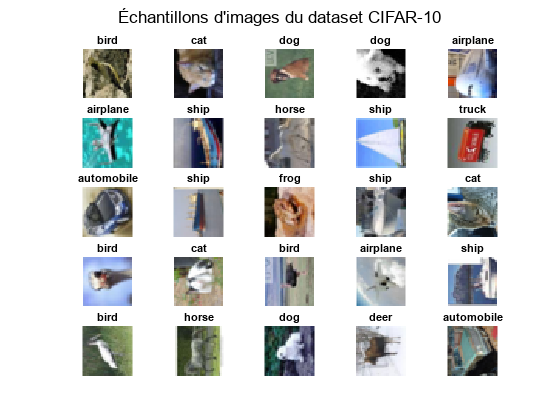


%% 2. Exploration et Visualisation des Données

% Afficher quelques images d'entraînement avec leurs labels
figure;
numImages = 25; % Nombre d'images à afficher
idx = randperm(size(trainImages, 4), numImages);
for i = 1:numImages
    subplot(5, 5, i);
    imshow(uint8(trainImages(:,:,:,idx(i)))); 
    title(string(trainLabels(idx(i))));
    axis off;
end
sgtitle('Échantillons d''images du dataset CIFAR-10');

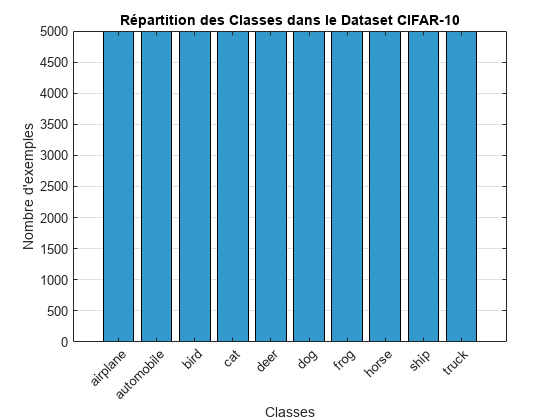


% Afficher le nombre d'éléments dans chaque classe
classCounts = countcats(trainLabels);

figure;
bar(classCounts, 'FaceColor', [0.2 0.6 0.8]);
xlabel('Classes');
ylabel('Nombre d''exemples');
title('Répartition des Classes dans le Dataset CIFAR-10');
xticklabels(classNames);
xtickangle(45);
grid on;


disp('Répartition des données par classe :');

Répartition des données par classe :


disp(table(classNames', classCounts, 'VariableNames', {'Classe', 'NombreExemples'}));

       Classe       NombreExemples
    ____________    ______________

    "airplane"           5000     
    "automobile"         5000     
    "bird"               5000     
    "cat"                5000     
    "deer"               5000     
    "dog"                5000     
    "frog"               5000     
    "horse"              5000     
    "ship"               5000     
    "truck"              5000     




%% 3. Préparation des Données 

% Définir la taille des entrées pour le modèle
inputSize = [32, 32, 3];

% Split the dataset into training (70%), validation (10%), and test (20%)
numTotalTrain = size(trainImages, 4); 
numTrain = round(0.8 * numTotalTrain);
numVal = round(0.2 * numTotalTrain);   
numTest = size(testImages, 4);         
rng(2001); 
idx = randperm(numTotalTrain);

% Split the data
trainImagesFinal = trainImages(:,:,:,idx(1:numTrain));
trainLabelsFinal = trainLabels(idx(1:numTrain));

valImages = trainImages(:,:,:,idx(numTrain+1:numTrain+numVal));
valLabels = trainLabels(idx(numTrain+1:numTrain+numVal));

testData = augmentedImageDatastore(inputSize, testImages, testLabels);
trainData = augmentedImageDatastore(inputSize, trainImagesFinal, trainLabelsFinal);
valData = augmentedImageDatastore(inputSize, valImages, valLabels);

disp('Préparation des données terminée.');

Préparation des données terminée.



%% 4. Création du Modèle CNN Personnalisé
layers = [
    imageInputLayer([32, 32, 3], 'Name', 'input', 'Normalization', 'zerocenter')
    
    % Bloc Convolutionnel 1
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1_1')
    batchNormalizationLayer('Name', 'bn1_1')
    reluLayer('Name', 'relu1_1')
    
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1_2')
    batchNormalizationLayer('Name', 'bn1_2')
    reluLayer('Name', 'relu1_2')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1')
    dropoutLayer(0.1, 'Name', 'dropout1')
    
    % Bloc Convolutionnel 2
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2_1')
    batchNormalizationLayer('Name', 'bn2_1')
    reluLayer('Name', 'relu2_1')
    
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2_2')
    batchNormalizationLayer('Name', 'bn2_2')
    reluLayer('Name', 'relu2_2')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2')
    dropoutLayer(0.2, 'Name', 'dropout2')
    
    % Bloc Convolutionnel 3
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv3_1')
    batchNormalizationLayer('Name', 'bn3_1')
    reluLayer('Name', 'relu3_1')
    
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv3_2')
    batchNormalizationLayer('Name', 'bn3_2')
    reluLayer('Name', 'relu3_2')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool3')
    dropoutLayer(0.25, 'Name', 'dropout3')
    
    % Nouveau Bloc Convolutionnel 4
    convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'conv4_1')
    batchNormalizationLayer('Name', 'bn4_1')
    reluLayer('Name', 'relu4_1')
    
    convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'conv4_2')
    batchNormalizationLayer('Name', 'bn4_2')
    reluLayer('Name', 'relu4_2')
    
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool4')
    dropoutLayer(0.35, 'Name', 'dropout4')

    % Fully Connected Layers
    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.5, 'Name', 'dropout_fc1')
    
    fullyConnectedLayer(10, 'Name', 'fc_output') % CIFAR-10: 10 classes
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')];

% Visualiser l'architecture
analyzeNetwork(layers);



%% 5. Entraînement du Modèle CNN Personnalisé
% Définir les options d'entraînement avec early stopping
options = trainingOptions('adam', ...
    'MaxEpochs', 30, ... 
    'MiniBatchSize', 128, ... % la taille du mini-batch
    'InitialLearnRate', 0.001, ... 
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.7, ... % Réduire le taux d'apprentissage
    'LearnRateDropPeriod', 4, ... % Réduction toutses les 4 epochs
    'Shuffle', 'every-epoch', ...
    'ValidationData', valData, ...
    'ValidationFrequency', 312, ... 
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu', ... % Entraînement sur GPU
    'ValidationPatience', 3);  % Arrêter si la précision ne s'améliore pas

% Entraîner le réseau
disp('Entraînement du modèle en cours...');

Entraînement du modèle en cours...


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       12.50% |       13.37% |       5.3064 |       2.8837 |          0.0010 |
|       1 |          50 |       00:00:05 |       27.34% |              |       2.0852 |              |          0.0010 |
|       1 |         100 |       00:00:08 |       29.69% |              |       1.8570 |              |          0.0010 |
|       1 |         150 |       00:00:10 |       32.81% |              |       1.8083 |              |          0.

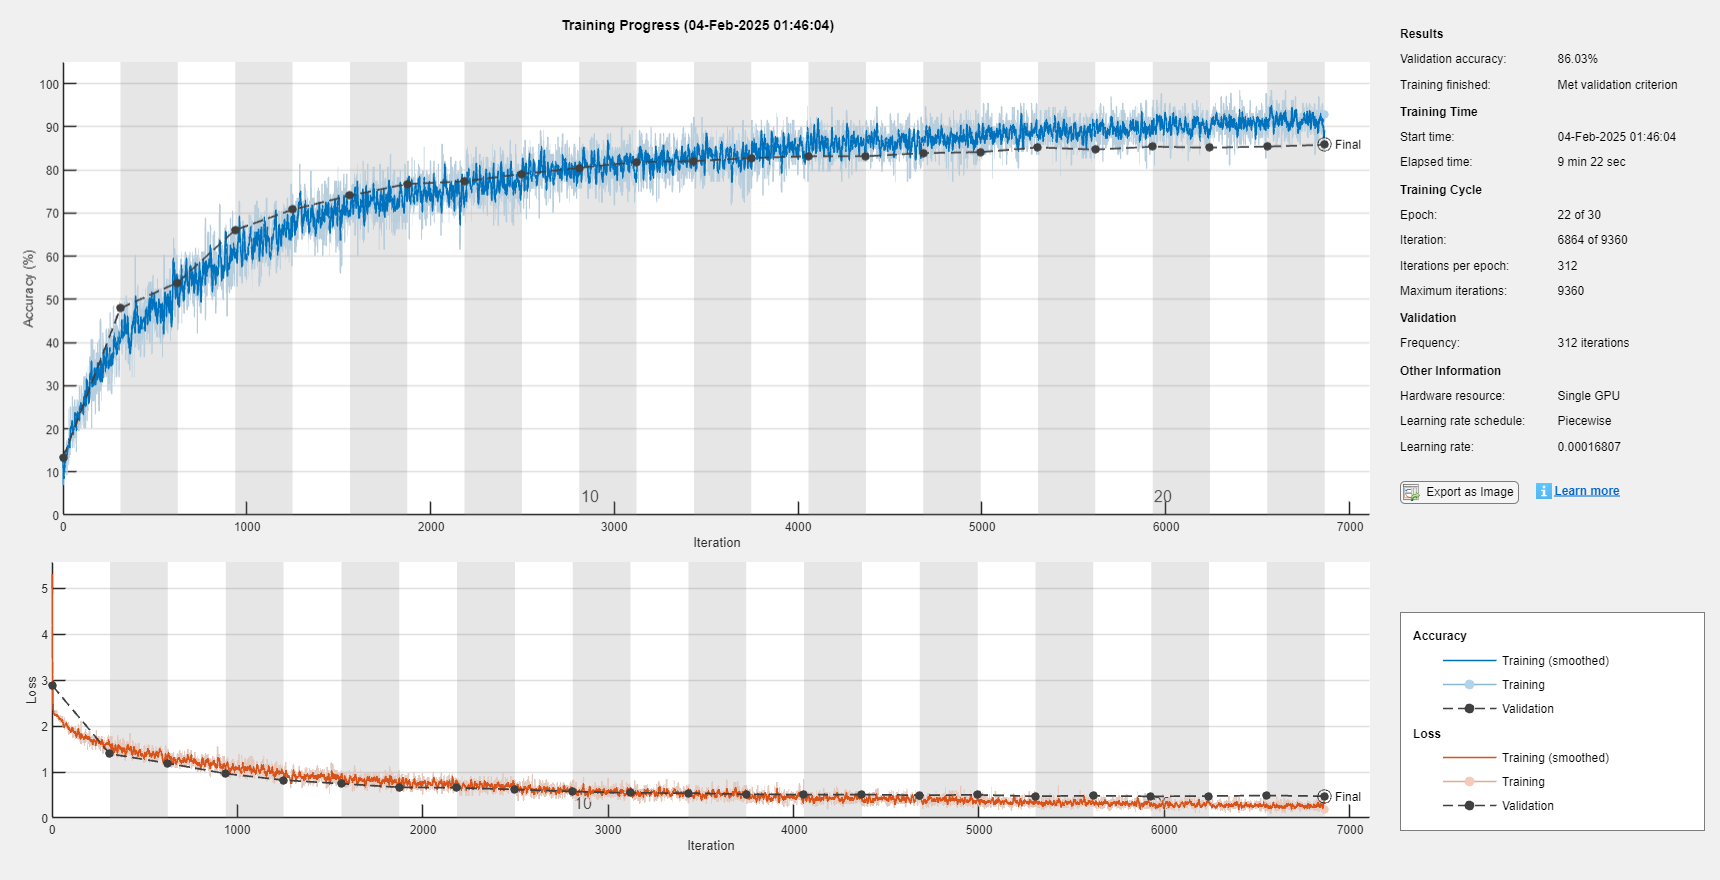

MetENet = trainNetwork(trainData, layers, options);

disp('Entraînement terminé.');

Entraînement terminé.



%% 6. Évaluation des Performances du Modèle

% Classification sur le jeu de test
[YPred, scores] = classify(MetENet, testData);
accuracy = mean(YPred == testLabels);
disp(['Accuracy du modèle personnalisé : ', num2str(accuracy * 100), '%']);

Accuracy du modèle personnalisé : 86.04%



% Calcul de la matrice de confusion brute
confMatrixRaw = confusionmat(testLabels, YPred);

% Calculer les vrais positifs (TP), faux positifs (FP) et faux négatifs (FN) par classe
TP = diag(confMatrixRaw);
FP = sum(confMatrixRaw, 1)' - TP;  % Somme de chaque colonne moins TP
FN = sum(confMatrixRaw, 2) - TP;     % Somme de chaque ligne moins TP

% Calcul des métriques par classe avec protection contre la division par zéro
precisionClass = TP ./ (TP + FP + eps);
recallClass    = TP ./ (TP + FN + eps);
f1Class        = 2 * (precisionClass .* recallClass) ./ (precisionClass + recallClass + eps);

% Affichage des métriques par classe
disp('Métriques par classe :');

Métriques par classe :


for i = 1:length(classNames)
    fprintf('Classe %s : Précision = %.2f%% | Rappel = %.2f%% | F1-score = %.2f%%\n', ...
        classNames(i), precisionClass(i)*100, recallClass(i)*100, f1Class(i)*100);
end

Classe airplane : Précision = 87.84% | Rappel = 88.10% | F1-score = 87.97%
Classe automobile : Précision = 95.11% | Rappel = 93.30% | F1-score = 94.19%
Classe bird : Précision = 80.52% | Rappel = 80.20% | F1-score = 80.36%
Classe cat : Précision = 74.47% | Rappel = 69.70% | F1-score = 72.00%
Classe deer : Précision = 81.12% | Rappel = 87.20% | F1-score = 84.05%
Classe dog : Précision = 80.81% | Rappel = 76.20% | F1-score = 78.44%
Classe frog : Précision = 87.30% | Rappel = 92.10% | F1-score = 89.64%
Classe horse : Précision = 89.31% | Rappel = 87.70% | F1-score = 88.50%
Classe ship : Précision = 92.02% | Rappel = 93.40% | F1-score = 92.70%
Classe truck : Précision = 91.22% | Rappel = 92.50% | F1-score = 91.86%



% Calcul des métriques globales
% Global Precision, Recall et F1-score (micro-moyenne)
globalPrecision = sum(TP) / (sum(TP) + sum(FP) + eps);
globalRecall    = sum(TP) / (sum(TP) + sum(FN) + eps);
globalF1Score   = 2 * (globalPrecision * globalRecall) / (globalPrecision + globalRecall + eps);

% Taux d'erreur global
errorRate = 1 - accuracy;

% Affichage des métriques globales
disp(' ');

disp('Évaluation globale de l''architecture :');

Évaluation globale de l'architecture :


fprintf('Accuracy           : %.2f%%\n', accuracy * 100);

Accuracy           : 86.04%


fprintf('Précision globale  : %.2f%%\n', globalPrecision * 100);

Précision globale  : 86.04%


fprintf('Rappel global      : %.2f%%\n', globalRecall * 100);

Rappel global      : 86.04%


fprintf('F1-score global    : %.2f%%\n', globalF1Score * 100);

F1-score global    : 86.04%


fprintf('Taux d''erreur     : %.2f%%\n', errorRate * 100);

Taux d'erreur     : 13.96%


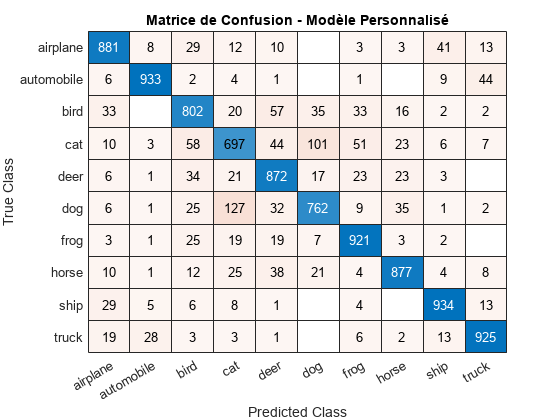


% Affichage de la matrice de confusion
figure;
confusionchart(testLabels, YPred);
title('Matrice de Confusion - Modèle Personnalisé');

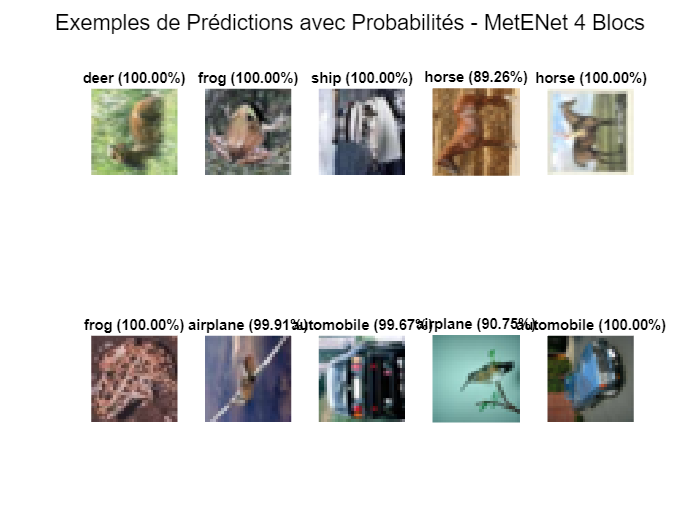


%% 6. Affichage des Prédictions
% Afficher des exemples avec les probabilités de chaque classe
figure;
numImagesToShow = 10; % Nombre d'exemples à afficher
indices = randperm(size(testImages, 4), numImagesToShow);

for i = 1:numImagesToShow
    subplot(2, 5, i);
    img = testImages(:, :, :, indices(i));
    imshow(uint8(img));
    
    % Afficher le label prédit et les probabilités
    label = YPred(indices(i));
    prob = scores(indices(i), :);
    
    % Titre avec le label et la probabilité correspondante
    [maxProb, maxIdx] = max(prob);
    title(sprintf('%s (%.2f%%)', classNames(maxIdx), maxProb * 100));
end
sgtitle('Exemples de Prédictions avec Probabilités - MetENet 4 Blocs');


% Save the trained network to a file
save('MetENet.mat', 'MetENet');


